# SUBIECT 16 IUNIE

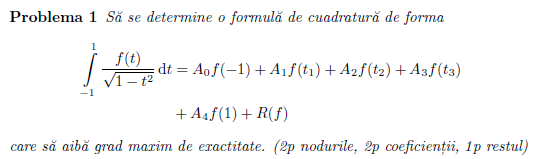

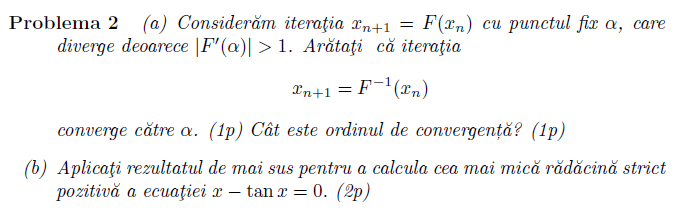

a) ${\left(F^{-1} \right)}^{\prime } \left(\alpha \right)=\frac{1}{F^{\prime } \left(\alpha \right)}$, iar cum $F^{\prime } \left(\alpha \right)$>1 => ${\left(F^{-1} \right)}^{\prime } \left(\alpha \right)$<1  si atunci converge spre $\alpha$.

b) Am modificat $\mathrm{atan}\left(x\right)+\pi$ ca sa obtinem cea mai mica radacina strict pozitiva, folosindu-ne de periodicitatea arctangentei. Radacina minima anterioara era 0.

syms x
g=@(x) atan(x)+pi;
[x_1,val,i]=aproximare_succesiva(g,0,1e-8,500)

x_1 =    4.493409456904118


val =    4.493409457861640


i =      8


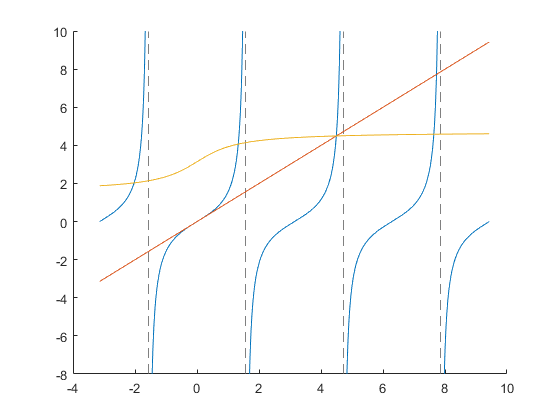

hold on
fplot([tan(x),x,atan(x)+pi],[-pi,3*pi])

x_1-tan(x_1)

ans =      2.029059853470017e-08


**FUNCTII**

function [x1, val_f, i] = aproximare_succesiva(f, x0, err, NrMaxIt)
    if nargin < 3
        err = 1e-12;
    end
    if nargin < 4
        NrMaxIt = 100;
    end

    x = zeros(1, NrMaxIt);
    x(1) = x0;

    for i = 1:NrMaxIt

        x(i+1) = f(x(i));

        if norm(f(x(i+1)), Inf) < err || norm(x(i+1) - x(i), Inf) < err ...
                || norm(x(i+1) - x(i), Inf) / norm(x(i+1), Inf) < err
            x1 = x(i+1);
            val_f = f(x1);
            return;
        end
    end

    x1 = x(end);
    val_f =f(x1);
end